Load train file

filename='Train_Arabic_Digit.txt';
fid = fopen(filename, 'r');
k=0;%added myself
while ~feof(fid)
    tline = fgetl(fid);
    values=sscanf(tline,'%f');
    if length(values)==0
        if k~=0
            XTrain{k,1}=tmp; tmp=[];
        end
        k=k+1;
        kk=1;
    else
        tmp(:,kk) = values(:)';
        kk=kk+1;
    end
end
XTrain{k,1}=tmp;
fclose(fid);

Create category set

lenx=length(XTrain)/10;
valueset = [0:9];
catnames = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'};
for k=0:9
y(k*lenx+(1:lenx))=k;
end
YTrain = categorical(y,valueset,catnames)';
clear fid filename k kk lenx tline tmp values y%clear variables

And so does test set

filename='Test_Arabic_Digit.txt';
fid = fopen(filename, 'r');
k=0;%added myself
while ~feof(fid)
    tline = fgetl(fid);
    values=sscanf(tline,'%f');
    if length(values)==0
        if k~=0
            XValid{k,1}=tmp; tmp=[];
        end
        k=k+1;
        kk=1;
    else
        tmp(:,kk) = values(:)';
        kk=kk+1;
    end
end
XValid{k,1}=tmp;
fclose(fid);
lenx=length(XValid)/10;
for k=0:9
y(k*lenx+(1:lenx))=k;
end
YValid = categorical(y,valueset,catnames)';
clear fid filename k kk lenx tline tmp values y%clear variables

Design network architecture

layers = [
    sequenceInputLayer(13,"Name","input")
    lstmLayer(300,"Name","lstm1","OutputMode","last")
    dropoutLayer(0.15,"Name","dropout1")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

Training options

options = trainingOptions('adam', ...
    'MiniBatchSize',66, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValid,YValid}, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',200, ...
    'Verbose',false, ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',8,...
    'LearnRateDropFactor',0.6,...
    'InitialLearnRate',0.002,...
    'Plots','training-progress',...
    'OutputNetwork','best-validation-loss');

Train the network

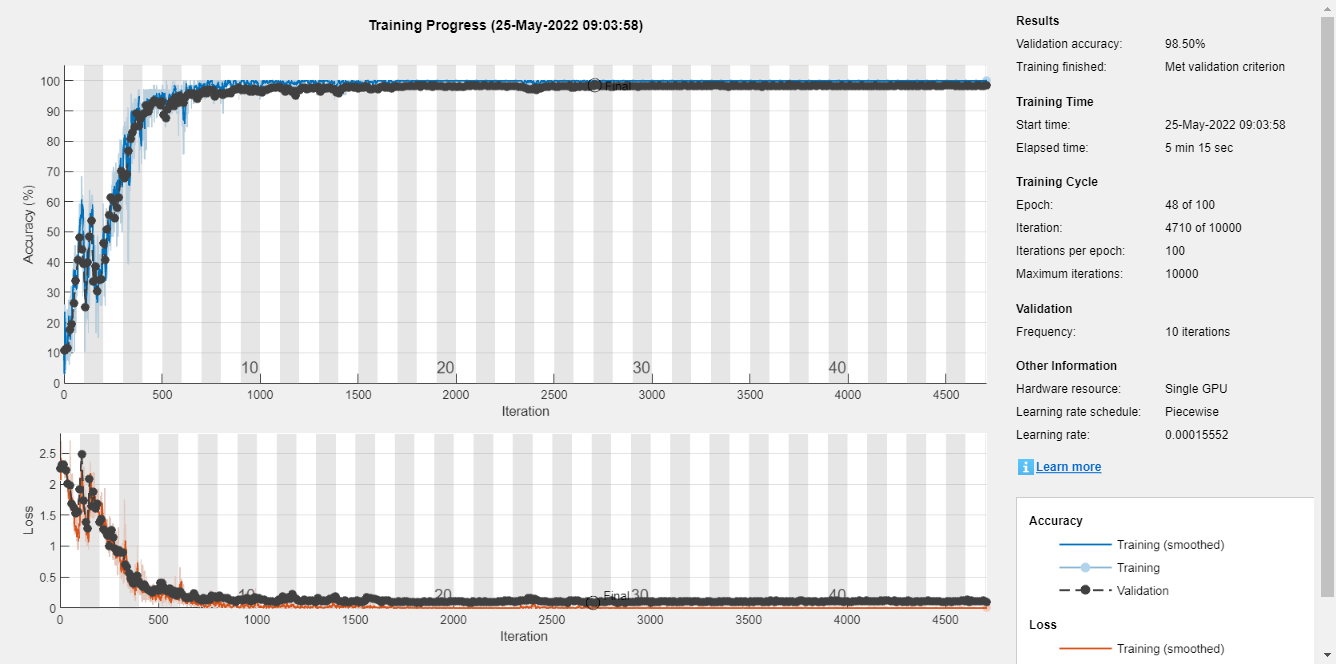

net = trainNetwork(XTrain,YTrain,layers,options);

Calculate accuracy

YPred = classify(net,XValid,"MiniBatchSize",66);
acc = mean(YPred == YValid)

acc = 0.9745

Confusion matrix

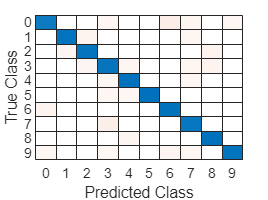

confusionchart(YValid,YPred);